f = @(x)(x^4-cos(x)+x)

f = function_handle with value:
    @(x)(x^4-cos(x)+x)


%row 1 is old and 2 is new 
xl = [0 nan];
xu = [1 nan];
needEror = 0.01;
numLoop = 50;
ezplot(f);

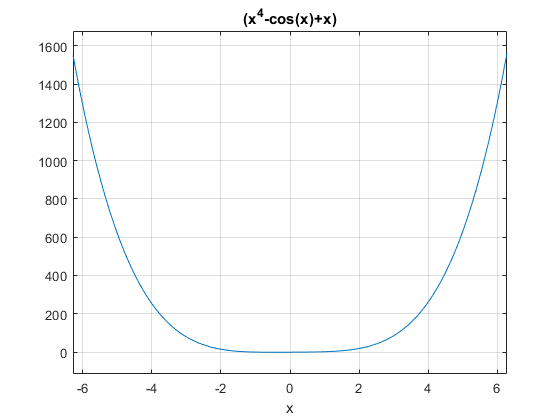

grid on;

format short;
fprintf("----------------------------------------------")

----------------------------------------------

%check function f f(xl)f(xu)<0
startXl = feval(f,xl(1));
startXU = feval(f,xu(1));
fprintf("f(xl) = %d",startXl)

f(xl) = -1

fprintf("f(xu) = %d",startXU)

f(xu) = 1.459698e+00

if(startXl*startXU<0)
   canstart = true;
end
if(canstart)
   fprintf("f(xl)*f(xl)<0 สามารถหา root ได้")
else
   fprintf("f(xl)*f(xl)>0 ไม่สามารถหา root ได้") 
end

f(xl)*f(xl)<0 สามารถหา root ได้

fprintf("xr = (xu+xl)/2 , error(เปอร์เซ็น) = (|ใหม่-เก่า|/ใหม่)*100")

xr = (xu+xl)/2 , error(เปอร์เซ็น) = (|ใหม่-เก่า|/ใหม่)*100

fprintf("----------------------------------------------")

----------------------------------------------

for i = 1:numLoop
    %find xr
    xr = (xl(1)+xu(1))/2;
    fprintf("xr = (%d + %d)/2 = %d",xl(1),xu(1),xr)
    %find value of funtion for xr
    fxr = feval(f,xr);
    fprintf("f(xr) = %s = %d",char(f),fxr)
    %check function
    fxl = feval(f,xl(1));
    if(fxl*fxr<0)
        fprintf("เมื่อ f(xl)*f(xr)<0")
        xu(2) = xr;
        error = abs((xu(2)-xu(1))/xu(2));
        fprintf("ใช้ xl= %d , xu = %d",xl(1),xu(2))
        fprintf("error = |%d-%d|/%d x 100 = %d ",xu(2),xu(1),xu(2),error*100)
        xu(1) = xu(2);
    else
        fprintf("เมื่อ f(xl)*f(xr)>0")
        xl(2) = xr;
        error = abs((xl(2)-xl(1))/xl(2));
        fprintf("ใช้ xl= %d , xu = %d",xl(2),xu(1))
        fprintf("error = |%d-%d|/%d x 100 = %d ",xl(2),xl(1),xl(2),error*100)
        xl(1) = xl(2);
    end
    fprintf("----------------------------------------------")
    %check error
    if(error<needEror)
        break;
    end

end

xr = (0 + 1)/2 = 5.000000e-01

f(xr) = @(x)(x^4-cos(x)+x) = -3.150826e-01

เมื่อ f(xl)*f(xr)>0

ใช้ xl= 5.000000e-01 , xu = 1

error = |5.000000e-01-0|/5.000000e-01 x 100 = 100 

----------------------------------------------

xr = (5.000000e-01 + 1)/2 = 7.500000e-01

f(xr) = @(x)(x^4-cos(x)+x) = 3.347174e-01

เมื่อ f(xl)*f(xr)<0

ใช้ xl= 5.000000e-01 , xu = 7.500000e-01

error = |7.500000e-01-1|/7.500000e-01 x 100 = 3.333333e+01 

----------------------------------------------

xr = (5.000000e-01 + 7.500000e-01)/2 = 6.250000e-01

f(xr) = @(x)(x^4-cos(x)+x) = -3.337523e-02

เมื่อ f(xl)*f(xr)>0

ใช้ xl= 6.250000e-01 , xu = 7.500000e-01

error = |6.250000e-01-5.000000e-01|/6.250000e-01 x 100 = 20 

----------------------------------------------

xr = (6.250000e-01 + 7.500000e-01)/2 = 6.875000e-01

f(xr) = @(x)(x^4-cos(x)+x) = 1.380690e-01

เมื่อ f(xl)*f(xr)<0

ใช้ xl= 6.250000e-01 , xu = 6.875000e-01

error = |6.875000e-01-7.500000e-01|/6.875000e-01 x 100 = 9.090909e+00 

----------------------------------------------

xr = (6.250000e-01 + 6.875000e-01)/2 = 6.562500e-01

f(xr) = @(x)(x^4-cos(x)+x) = 4.943568e-02

เมื่อ f(xl)*f(xr)<0

ใช้ xl= 6.250000e-01 , xu = 6.562500e-01

error = |6.562500e-01-6.875000e-01|/6.562500e-01 x 100 = 4.761905e+00 

----------------------------------------------

xr = (6.250000e-01 + 6.562500e-01)/2 = 6.406250e-01

f(xr) = @(x)(x^4-cos(x)+x) = 7.331127e-03

เมื่อ f(xl)*f(xr)<0

ใช้ xl= 6.250000e-01 , xu = 6.406250e-01

error = |6.406250e-01-6.562500e-01|/6.406250e-01 x 100 = 2.439024e+00 

----------------------------------------------

xr = (6.250000e-01 + 6.406250e-01)/2 = 6.328125e-01

f(xr) = @(x)(x^4-cos(x)+x) = -1.319331e-02

เมื่อ f(xl)*f(xr)>0

ใช้ xl= 6.328125e-01 , xu = 6.406250e-01

error = |6.328125e-01-6.250000e-01|/6.328125e-01 x 100 = 1.234568e+00 

----------------------------------------------

xr = (6.328125e-01 + 6.406250e-01)/2 = 6.367188e-01

f(xr) = @(x)(x^4-cos(x)+x) = -2.974344e-03

เมื่อ f(xl)*f(xr)>0

ใช้ xl= 6.367188e-01 , xu = 6.406250e-01

error = |6.367188e-01-6.328125e-01|/6.367188e-01 x 100 = 6.134969e-01 

----------------------------------------------